%Variables needed for lowpass butter function
Omega_c = pi/3;
Fs = 1000; % Sampling frequency (not specified in problem)
Fc = Omega_c/(Fs/2) % Cutoff frequency = Omega_c / (Sample frequecy/2) normalized

Fc = 0.0021

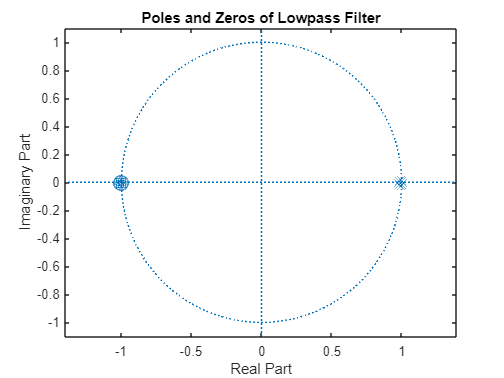

% Eighth-order digital lowpass filter
[b_low, a_low] = butter(8, Fc, 'low');
figure;
zplane(b_low, a_low);
title('Poles and Zeros of Lowpass Filter');

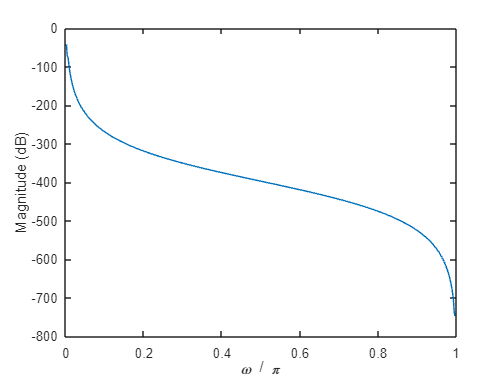

[h,w] = freqz(b_low,a_low);
dB = mag2db(abs(h)); %dB = 20 log10(|h|).
plot(w/pi,dB)
xlabel('\omega / \pi')
ylabel('Magnitude (dB)')